# Lab 1 - EMG

Dua Kaurejo

## Lab Goal

Using the dataset provided, your goal is to identify the order of the  gestures made by the participant. 

Each data file contains three channels of data (in signal variable, see  “Tools” slide). Each of those three channels is referenced to an  electrode on the FCR. The channels are 1 = FCR1; 2 = ECR1; 3 = ECR2.  There was a reference electrode on the wrist. 

There are three gestures: flex, extend, and squeeze. Each gesture is  performed twice.

*Sampling frequency Fs = 512Hz*

close all; clear; clc
load('lab1_data.mat')

Uses a linear combination of the channels to create a bipolar EMG signal for  the FCR and ECR.

fcr = signal(:, 1);
ecr1 = signal(:,2);
ecr2 = signal(:,3);

ecr = ecr1 - ecr2; % bipolar ecr

ecr_fcr = [fcr, ecr];

Gestures: Flex, Extend, Squeeze, each gesture performed twice

Squeeze --> Both

- high fcr (higher than flex gesture)

- low ecr

Flex --> fcr

- high fcr (not as high as squeeze)

- low ecr

Extend --> ecr

- low fcr

- high ecr

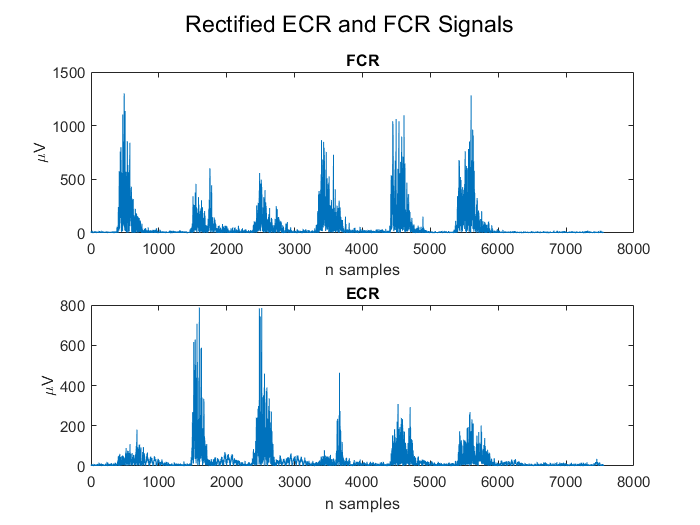

rectified_ecrfcr = abs(ecr_fcr);
figure
sgtitle('Rectified ECR and FCR Signals')
subplot(2,1,1)
plot(rectified_ecrfcr(:,1))
title('FCR')
xlabel('n samples')
ylabel('\muV')
subplot(2,1,2)
plot(rectified_ecrfcr(:,2))
title('ECR')


xlabel('n samples')
ylabel('\muV')

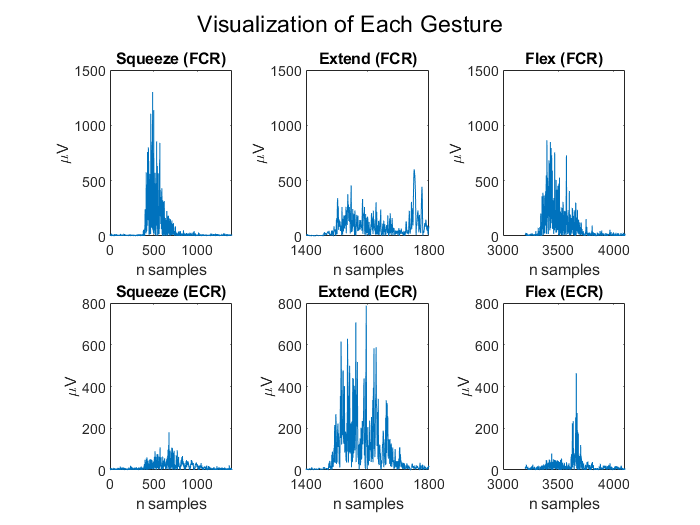


figure

subplot(2,3,1)
plot(1:1400,rectified_ecrfcr(1:1400,1))
title('Squeeze (FCR)')
ylim([0 1500])
ylabel('\muV')
xlabel('n samples')

subplot(2,3,2)
plot(1400:1800, rectified_ecrfcr(1400:1800,1))
ylim([0 1500])
title('Extend (FCR)')
ylim([0 1500])
ylabel('\muV')
xlabel('n samples')

subplot(2,3,3)
plot(3200:4100, rectified_ecrfcr(3200:4100,1))
ylim([0 1500])
title('Flex (FCR)')
ylim([0 1500])
ylabel('\muV')
xlabel('n samples')

subplot(2,3,4)
plot(1:1400, rectified_ecrfcr(1:1400,2))
title('Squeeze (ECR)')
ylim([0 800])
ylabel('\muV')
xlabel('n samples')

subplot(2,3,5)
plot(1400:1800, rectified_ecrfcr(1400:1800,2))
ylim([0 1500])
title('Extend (ECR)')
ylim([0 800])
ylabel('\muV')
xlabel('n samples')

subplot(2,3,6)
plot(3200:4100, rectified_ecrfcr(3200:4100,2))
ylim([0 1500])
title('Flex (ECR)')
ylim([0 800])
ylabel('\muV')
xlabel('n samples')
sgtitle('Visualization of Each Gesture')

NOTE: Below code not used for lab report. 

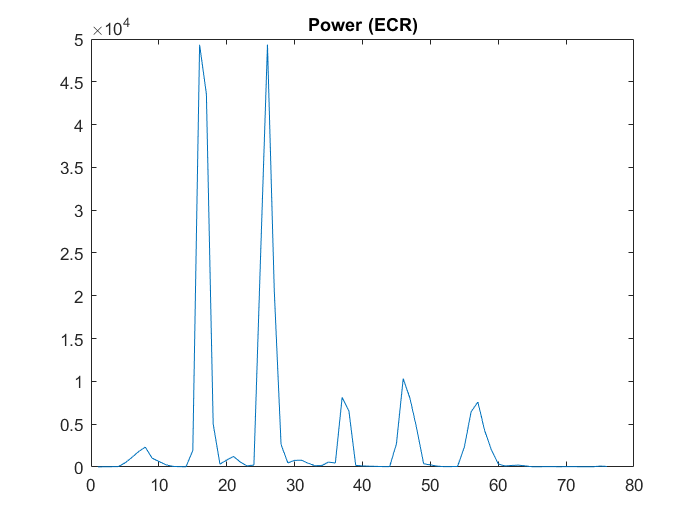

%ecr_fcr = [fcr, ecr];
%rectified_ecrfcr
windowSize = 150; 
overlap = 50;

rectECR = rectified_ecrfcr(:,2);
rectFCR = rectified_ecrfcr(:,1);

buffered_ECR = buffer(rectECR, windowSize, overlap, "nodelay");
buffered_FCR = buffer(rectFCR, windowSize, overlap, "nodelay");

power_ecr = mean(buffered_ECR.^2,1);
power_fcr = mean(buffered_FCR.^2,1);

figure
plot(power_ecr)
title('Power (ECR)')

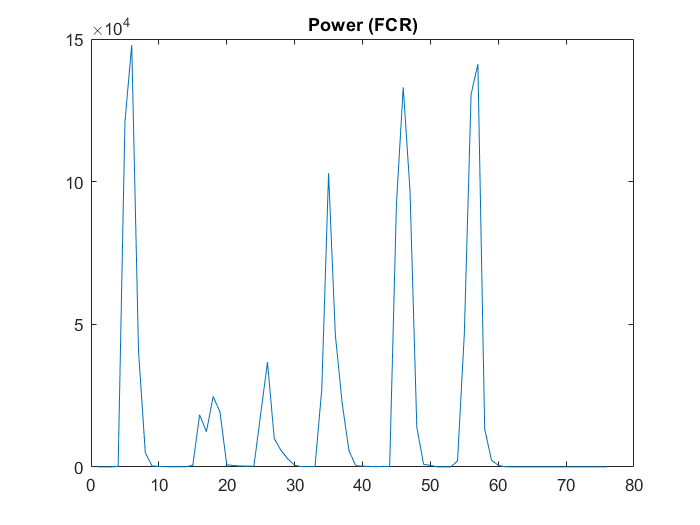

figure
plot(power_fcr)
title('Power (FCR)')